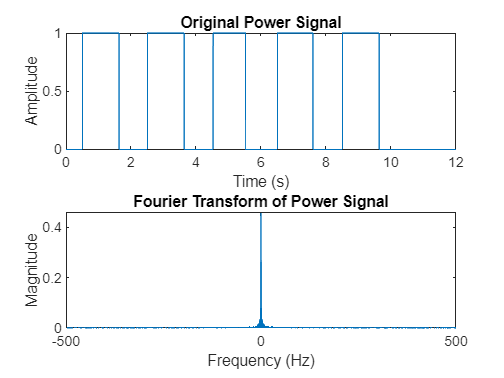

% Power System Analysis using Fourier Transform
clear; clc;

% Load the power system signal data from CSV
data = readmatrix('detect_dataset.csv'); % Replace with your own CSV file

% Extract the power signal column from the data
power_signal = data(:, 1); % Assuming power signal is in the first column

% Define the sampling frequency and time vector
fs = 1000; % Sample rate (Hz)
t = (0:length(power_signal)-1)/fs; % Time vector

% Perform Fourier Transform
N = length(power_signal); % Number of samples
f = (-N/2:N/2-1)*(fs/N); % Frequency vector
power_signal_fft = fftshift(fft(power_signal));

% Plot the original signal in time domain
figure;
subplot(2, 1, 1);
plot(t, power_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Power Signal');

% Plot the Fourier Transform of the signal in frequency domain
subplot(2, 1, 2);
plot(f, abs(power_signal_fft)/N);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Power Signal');


% Additional analysis (optional):
% Detect and analyze harmonic components, transient events, etc.

% Example: Find and display the dominant frequency component
[~, index] = max(abs(power_signal_fft));
dominant_frequency = abs(f(index));
disp(['Dominant Frequency: ', num2str(dominant_frequency), ' Hz']);

Dominant Frequency: 0.041663 Hz


% Load the power system signal data from CSV
data = csvread('detect_dataset.csv', 1, 0); % Replace with your own CSV file

% Extract the power signal column from the data
power_signal = data(:, 1); % Assuming power signal is in the first column
